
n=100;

x=linspace(0,1,n);

x=x';

f=@(x) sin(x);

signal=f(x);

sampling_rate=1;

% Empty matrix for the answers for later
y = zeros(n,1);

% define j so that it can be used later
j = 1i;

for k = 1:n
    for l = 1:n
        % Carry out the summation
        y(k) = y(k) + signal(l) * exp((-pi * j * l * k * 2) / n);
    end
end

fourier_transform=table(x,signal,y)

fourier_transform = 100×3 table
       x         signal             y        
    ________    ________    _________________

           0           0    -0.78186+13.908i 
    0.010101    0.010101     0.12947+6.8117i 
    0.020202    0.020201     0.29435+4.5174i 
    0.030303    0.030298     0.35178+3.3759i 
    0.040404    0.040393     0.37831+2.6911i 
    0.050505    0.050484      0.3927+2.2337i 
    0.060606    0.060569     0.40138+1.9059i 
    0.070707    0.070648     0.40701+1.659i  
    0.080808     0.08072     0.41087+1.466i  
    0.090909    0.090784     0.41363+1.3108i 
     0.10101     0.10084     0.41567+1.1829i 
     0.11111     0.11088     0.41722+1.0756i 
     0.12121     0.12092     0.41843+0.98409i
     0.13131     0.13094     0.41938+0.90497i
     0.14141     0.14094     0.42015+0.83576i
     0.15152     0.15094     0.42078+0.77459i


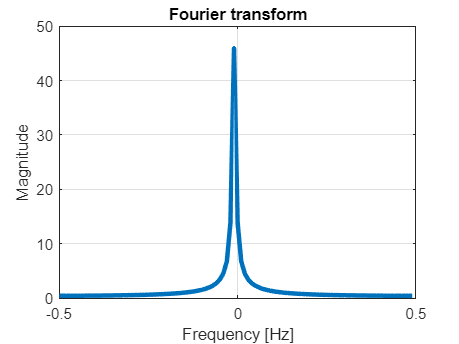


if mod(n,2)==0
    kmid=n/2;
else
    kmid=(n+1)/2;
end

kpos=0:kmid-1;
kneg=kmid:n-1;

freq=[kneg/n-1,kpos/n];



F=freq*sampling_rate;

y=y([kneg,kpos]+1);

plot(F,abs(y),'Linewidth',3)
xlabel('Frequency [Hz]');
ylabel('Magnitude');
grid on
title('Fourier transform')